# LSUN によるBurgers方程式の解析

最初にTanSacNet/code/**setpath **を実行してください。

Requirements: MATLAB R2022b

 Contact address: Shogo MURAMATSU,

        Faculty of Engineering, Niigata University,

        8050 2-no-cho Ikarashi, Nishi-ku,

        Niigata, 950-2181, JAPAN

        [http://msiplab.eng.niigata-u.ac.jp](http://msiplab.eng.niigata-u.ac.jp)  

 Copyright (c) 2023, Hayato Obara and Shogo MURAMATSU, All rights reserved.

clc, clear
close all

### Burgers方程式の条件設定

mu = 1;                                  %移流係数(1に固定)
nu = 0.05;                               %粘性係数(微分方程式のνに対応)

% Spatial Mesh
L_x = 10;                                %空間方向の最大値
dx = 0.1;                   
N_x = floor(L_x/dx);                     %空間方向のメッシュの総数
X = linspace(0,L_x,N_x);                 %座標

% Temporal Mesh
L_t = 10;                                %時間方向の最大値
dt = 0.1;                   
N_t = floor(L_t/dt);                     %時間方向のメッシュの総数
T = linspace(0,L_t,N_t);                 %座標

% Wave number discretization
k = 2*pi*fftfreq(N_x, dx);

% initial condition 
u0 = exp(-(X-3).^2/2); 
%u0 = np.sin(2*np.pi*X/L_x)

### データ作成

%PDE resolution (ODE system resolution)
opt = odeset('MaxStep',5000);
[~,DataT] = ode45(@(t,u) burg_system(u,t,k,mu,nu),T,u0,opt);

### データ可視化

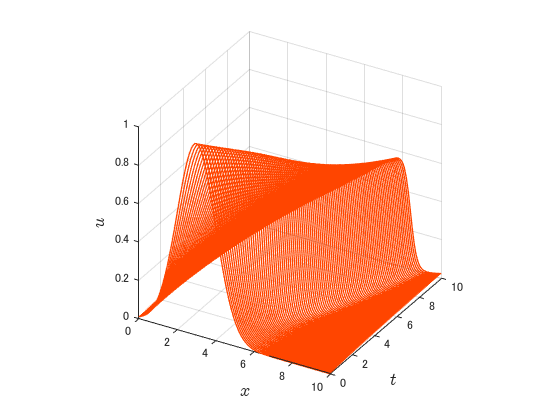

figure
orangered = [255 69 0]/255;
disp_plot3_(T,X,DataT,orangered)

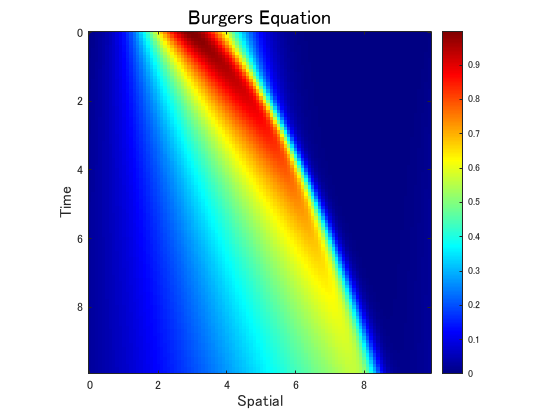

figure
disp_imagesc_(T,X,DataT)

### 設定

データサイズ

nT = size(DataT,1);
nX = size(DataT,2);

ストライド（ブロックサイズ）

pt = 2;
stride = 2*pt; % ストライド（偶数）
assert(mod(nX,stride)==0,'stride must be a divisor of nX.'); 

出力次元（ブロック辺り）

nCoefs = 2; 
assert(nCoefs<=stride,'nCoefs must be less than or equal to stride.')

重複ブロック数（シフト回数）

nof = 1;
kx = 2*nof+1; % 重複ブロック数（奇数）


設定表示

strbuf = "-- 設定 --" + newline;
strbuf = strbuf.append("データサイズ（空間）: " + num2str(nX) + newline);
strbuf = strbuf.append("データサイズ（時間）: " + num2str(nT) + newline);
strbuf = strbuf.append("ブロックサイズ: " + num2str(stride) + newline);
strbuf = strbuf.append("出力次元（ブロック辺り）: " + num2str(nCoefs) + newline);
strbuf = strbuf.append("重複ブロック数: " + num2str(kx) + newline);
disp(strbuf)

-- 設定 --
データサイズ（空間）: 100
データサイズ（時間）: 100
ブロックサイズ: 4
出力次元（ブロック辺り）: 2
重複ブロック数: 3



## Global block PCA for reference

nBlks = nX/stride;
% Reshape
blks = reshape(DataT,nT,stride,nBlks); % nT x stride x nBlks
blks = reshape(permute(blks,[2 1 3]),stride,[]); % stride x (nT*kx)
% PCA
%Vpca = pca(blks.')
mu = mean(blks,2);
blkszm = blks - mu;
C = cov(blkszm.');
[~,S,V] = svd(C,"econ");
[~,idxS] = sort(diag(S),"descend");
V = V(:,idxS(1:nCoefs));
%norm(Vpca - Vsvd,'fro')
% Approxiamtion
targetblks = reshape(...
    permute(reshape(DataT,nT,stride,nBlks),[2 1 3]),...
    stride,[]);
gbpcaseq = reshape(...
    ipermute(reshape((V*V.'*(targetblks-mu) + mu),stride,nT,nBlks),[2 1 3]),...
    nT,nX);

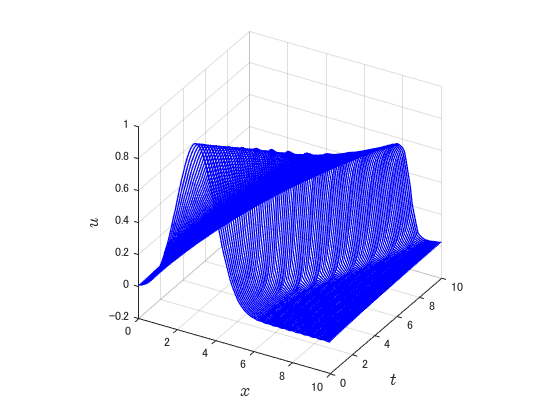

figure
disp_plot3_(T,X,gbpcaseq)

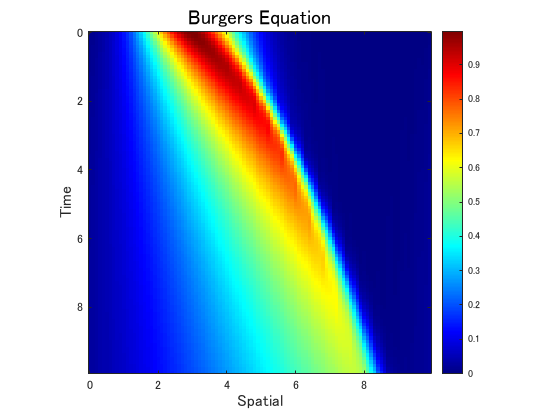

figure
disp_imagesc_(T,X,gbpcaseq)

% MSE評価
mse(DataT,gbpcaseq)

ans = 1.5155e-05

## Local block PCA for reference

lbpcaseq = zeros(nT,nX);
nBlks = nX/stride;
for iBlk = 1:nBlks
    % 重複ブロックの抽出 (周期拡張）
    subblks = fcn_extract_blks_(DataT,iBlk,stride,kx);
    % Reshape
    blks = reshape(subblks,nT,stride,kx); % nT x stride x kx
    blks = reshape(permute(blks,[2 1 3]),stride,[]); % stride x (nT*kx)
    % PCA
    %Vpca = pca(blks.')
    mu = mean(blks,2);
    blkszm = blks - mu;
    C = cov(blkszm.');
    [~,S,V] = svd(C,"econ");
    [~,idxS] = sort(diag(S),"descend");
    V = V(:,idxS(1:nCoefs));
    %norm(Vpca - Vsvd,'fro')
    % Approxiamtion
    targetblk = fcn_extract_blks_(DataT,iBlk,stride,1);
    approxblk = (V*V.'*(targetblk.'-mu)+mu).';
    % Place block
    lbpcaseq = fcn_place_blks_(lbpcaseq,approxblk,iBlk,stride);
end

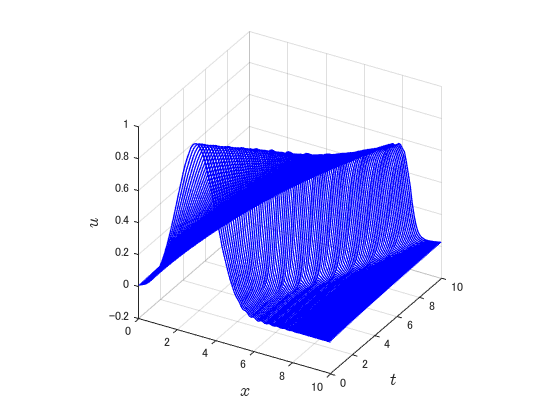

figure
disp_plot3_(T,X,lbpcaseq)

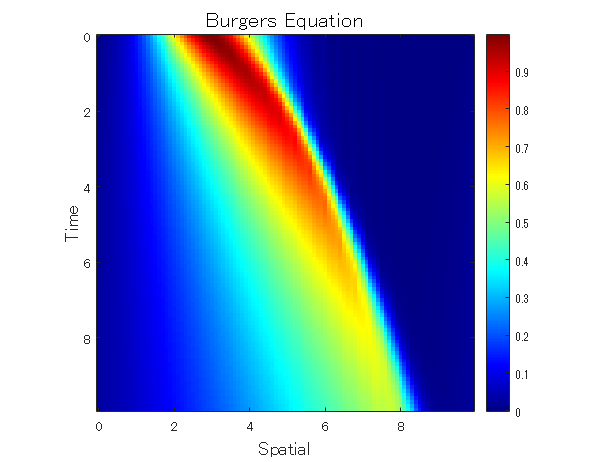

figure
disp_imagesc_(T,X,lbpcaseq)

% MSE評価
mse(DataT,lbpcaseq)

ans = 1.2171e-05

### 一次元局所構造化ユニタリネットワーク(1-D LSUN)の構築

参考文献

- Lu Gan and Kai-Kuang Ma, "On simplified order-one factorizations of paraunitary filterbanks," in IEEE Transactions on Signal Processing, vol. 52, no. 3, pp. 674-686, March 2004, [doi: 10.1109/TSP.2003.822356](https://doi.org/10.1109/TSP.2003.822356).

オリジナルPUFBの構成

    
$$\mathbf{E}(z)=\bar{\mathbf{U}}_{K-1}(z)\bar{\mathbf{U}}_{K-2}(z)\cdots\bar{\mathbf{U}}_{2}(z)\bar{\mathbf{U}}_{1}(z)\mathbf{U}_{0}$$


    
$$\bar{\mathbf{U}}_k(z)=\bar{\mathbf{U}}_k\mathbf{\Lambda}(z)$$


偶数チャネル実係数対称遅延分解(Real SDF)構成 [Fig. 7 (b), Gan *et al,*. IEEE T-SP, 2004]

- チャネル数 $M=2m$

- 
$$r_k=m$$


    
$$\bar{\mathbf{U}}_k = \mathrm{diag}(\bar{\mathbf{V}}_{k,0},\bar{\mathbf{V}}_{k,1})\bar{\mathbf{\Sigma}}_k$$


    $\bar{\mathbf{\Sigma}}_k = \left(\begin{array}{cc} \mathbf{C}_k & -\bar{\mathbf{S}}_k \\ \bar{\mathbf{S}}_k & \mathbf{C}_k \end{array} \right)$,

    
$$\mathbf{C}_k=\mathrm{diag}(\cos\alpha_{k,0},\cos\alpha_{k,1},\cdots,\cos\alpha_{k,m-1})$$


    
$$\bar{\mathbf{S}}_k=\mathrm{diag}(\sin\alpha_{k,0},\sin\alpha_{k,1},\cdots,\sin\alpha_{k,m-1})$$


    
$$\mathbf{\Lambda}(z)  = \mathrm{diag}(\mathbf{I}_m, z^{-1}\mathbf{I}_m)$$


空間的な非因果性を許容してステージ数 $(K-1)$ （ポリフェーズ次数 $N$）を偶数 $2n$ に設定

    
$$\mathbf{E}(z)=z^{-n} \bar{\mathbf{G}}_{n}(z)\bar{\mathbf{G}}_{n-1}(z)\cdots\bar{\mathbf{G}}_{1}(z)\mathbf{U}_{0}$$


    
$$\bar{\mathbf{G}}_n(z)=\bar{\mathbf{U}}_{2n}\check{\mathbf{\Lambda}}(z)\bar{\mathbf{U}}_{2n-1}\mathbf{\Lambda}(z)$$


    
$$\check{\mathbf{\Lambda}}(z)  = z^{+1}\mathbf{\Lambda}(z)= \mathrm{diag}(z^{+1}\mathbf{I}_m, \mathbf{I}_m)$$


修正非因果PUFB

    
$$\check{\mathbf{E}}(z)=\bar{\mathbf{G}}_{n}(z)\bar{\mathbf{G}}_{n-1}(z)\cdots\bar{\mathbf{G}}_{1}(z)\mathbf{U}_{0}$$


### 修正非因果PUFBのLSUN拡張

カスタムネットワーク構築

- [カスタム深層学習層の定義 - MATLAB & Simulink - MathWorks 日本](https://jp.mathworks.com/help/deeplearning/ug/define-custom-deep-learning-layers.html)

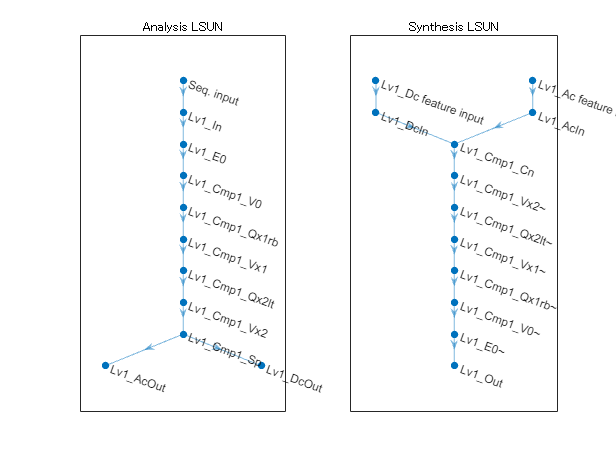

import tansacnet.lsun.*
analysislgraph = fcn_createcslsunlgraph1d([],...
    'InputSize',nX,...
    'Stride',stride,...
    'OverlappingFactor',kx,...
    'Mode','Analyzer');
synthesislgraph = fcn_createcslsunlgraph1d([],...
    'InputSize',nX,...
    'Stride',stride,...
    'OverlappingFactor',kx,...
    'Mode','Synthesizer');
figure
subplot(1,2,1)
plot(analysislgraph)
title('Analysis LSUN')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis LSUN')

### 設計パラメータの初期化

% Standard deviation of initial angles
stdInitAng = 1e-9;

% Construction of synthesis network.
analysisnet = dlnetwork(analysislgraph);

% Initialize
nLearnables = height(analysisnet.Learnables);
expanalyzer = '^Lv\d+_Cmp\d+_Q(\w\d|0)+(\w)+$';
nLayers = height(analysislgraph.Layers);
for iLearnable = 1:nLearnables
    if analysisnet.Learnables.Parameter(iLearnable)=="Angles"
        alayerName = analysisnet.Learnables.Layer(iLearnable);
        if ~isempty(regexp(alayerName,expanalyzer,'once'))
            disp("Angles in " + alayerName + " are set to N(-pi/2,"+num2str(stdInitAng^2)+")")
            analysisnet.Learnables.Value(iLearnable) = ...
                cellfun(@(x) x+stdInitAng*randn(size(x))-pi/2, ...
                analysisnet.Learnables.Value(iLearnable),'UniformOutput',false);
        else
            disp("Angles in " + alayerName + " are set to N(0,"+num2str(stdInitAng^2)+")")
            analysisnet.Learnables.Value(iLearnable) = ...
                cellfun(@(x) x+stdInitAng*randn(size(x)), ...
                analysisnet.Learnables.Value(iLearnable),'UniformOutput',false);
        end
    end
end

Angles in Lv1_Cmp1_V0 are set to N(0,1e-18)


Angles in Lv1_Cmp1_Qx1rb are set to N(-pi/2,1e-18)


Angles in Lv1_Cmp1_Vx1 are set to N(0,1e-18)


Angles in Lv1_Cmp1_Qx2lt are set to N(-pi/2,1e-18)


Angles in Lv1_Cmp1_Vx2 are set to N(0,1e-18)


### 随伴関係の構築

設計パラメータのコピー

import tansacnet.lsun.*
% Construction of analysis network
analysislgraph = layerGraph(analysisnet);
synthesislgraph = fcn_cpparamsana2syn(synthesislgraph,analysislgraph);

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vx1 to Lv1_Cmp1_Vx1~
Copy angles from Lv1_Cmp1_Vx2 to Lv1_Cmp1_Vx2~


synthesislgraph = fcn_cpparamsana2syn_csax_(synthesislgraph,analysislgraph);

Copy angles from Lv1_Cmp1_Qx1rb to Lv1_Cmp1_Qx1rb~
Copy angles from Lv1_Cmp1_Qx2lt to Lv1_Cmp1_Qx2lt~


synthesisnet = dlnetwork(synthesislgraph);

### 随伴関係（完全再構成）の確認

x = rand([1 nX 1 nT],'double');
dlx = dlarray(x,"SSCB"); % Deep learning array (SSCB)
[dls{1:2}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{:});
mse_ = mse(dlx,dly);
display("MSE: " + num2str(mse_))

    "MSE: 4.183e-14"



assert(mse_<1e-6)

### 設計パラメータの最適化と信号近似

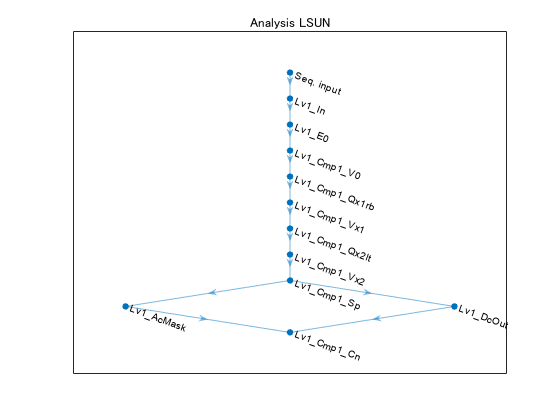

import tansacnet.lsun.*
analysislgraph = layerGraph(analysisnet);

% Coefficient masking
nChsTotal = prod(stride);
coefMask = reshape([ones(nCoefs,1); zeros(nChsTotal-nCoefs,1)],2,[]).';
coefMask = coefMask(:);
%nLevels = 1;
%for iLv = nLevels:-1:1
iLv = 1;
strLv = sprintf('Lv%0d_',iLv);
% For AC
analysislgraph = analysislgraph.replaceLayer([strLv 'AcOut'],...
    mask1dLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
%strLvPre = strLv;
%end

% Output layer
iCmp = 1;
strCmp = sprintf('Cmp%0d_',iCmp);
%analysislgraph = analysislgraph.addLayers([...
%      lsunChannelConcatenation1dLayer('Name',[strLv strCmp 'Cn']) ...
%      lsunRegressionLayer('Coefficient output')
%     ]);
analysislgraph = analysislgraph.addLayers(...
      lsunChannelConcatenation1dLayer('Name',[strLv strCmp 'Cn']));
analysislgraph = analysislgraph.connectLayers(...
    [strLv 'AcMask' ], [strLv strCmp 'Cn/ac']);
analysislgraph = analysislgraph.connectLayers(...
    [strLv 'DcOut' ], [strLv strCmp 'Cn/dc']);

figure
plot(analysislgraph)
title('Analysis LSUN')

### 数列データを1-D画像としてデータストアより読込

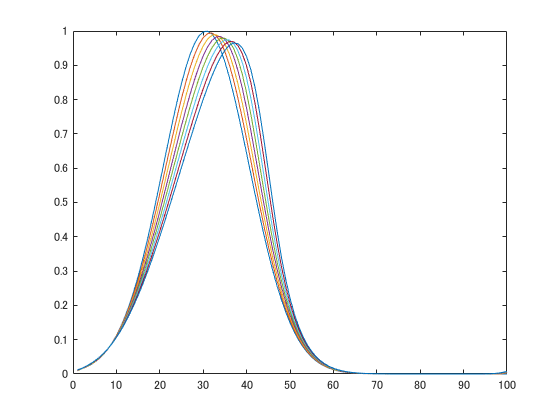

% Load sequences
arrds = arrayDatastore(DataT,"ReadSize",1,"IterationDimension",1);
%arrds = transform(arrds,@(x) cell2mat(x));
figure
arr = cell2mat(preview(arrds));
for idx = 1:height(arr)
    plot(arr(idx,:))
    hold on
end
hold off

### 設計準備

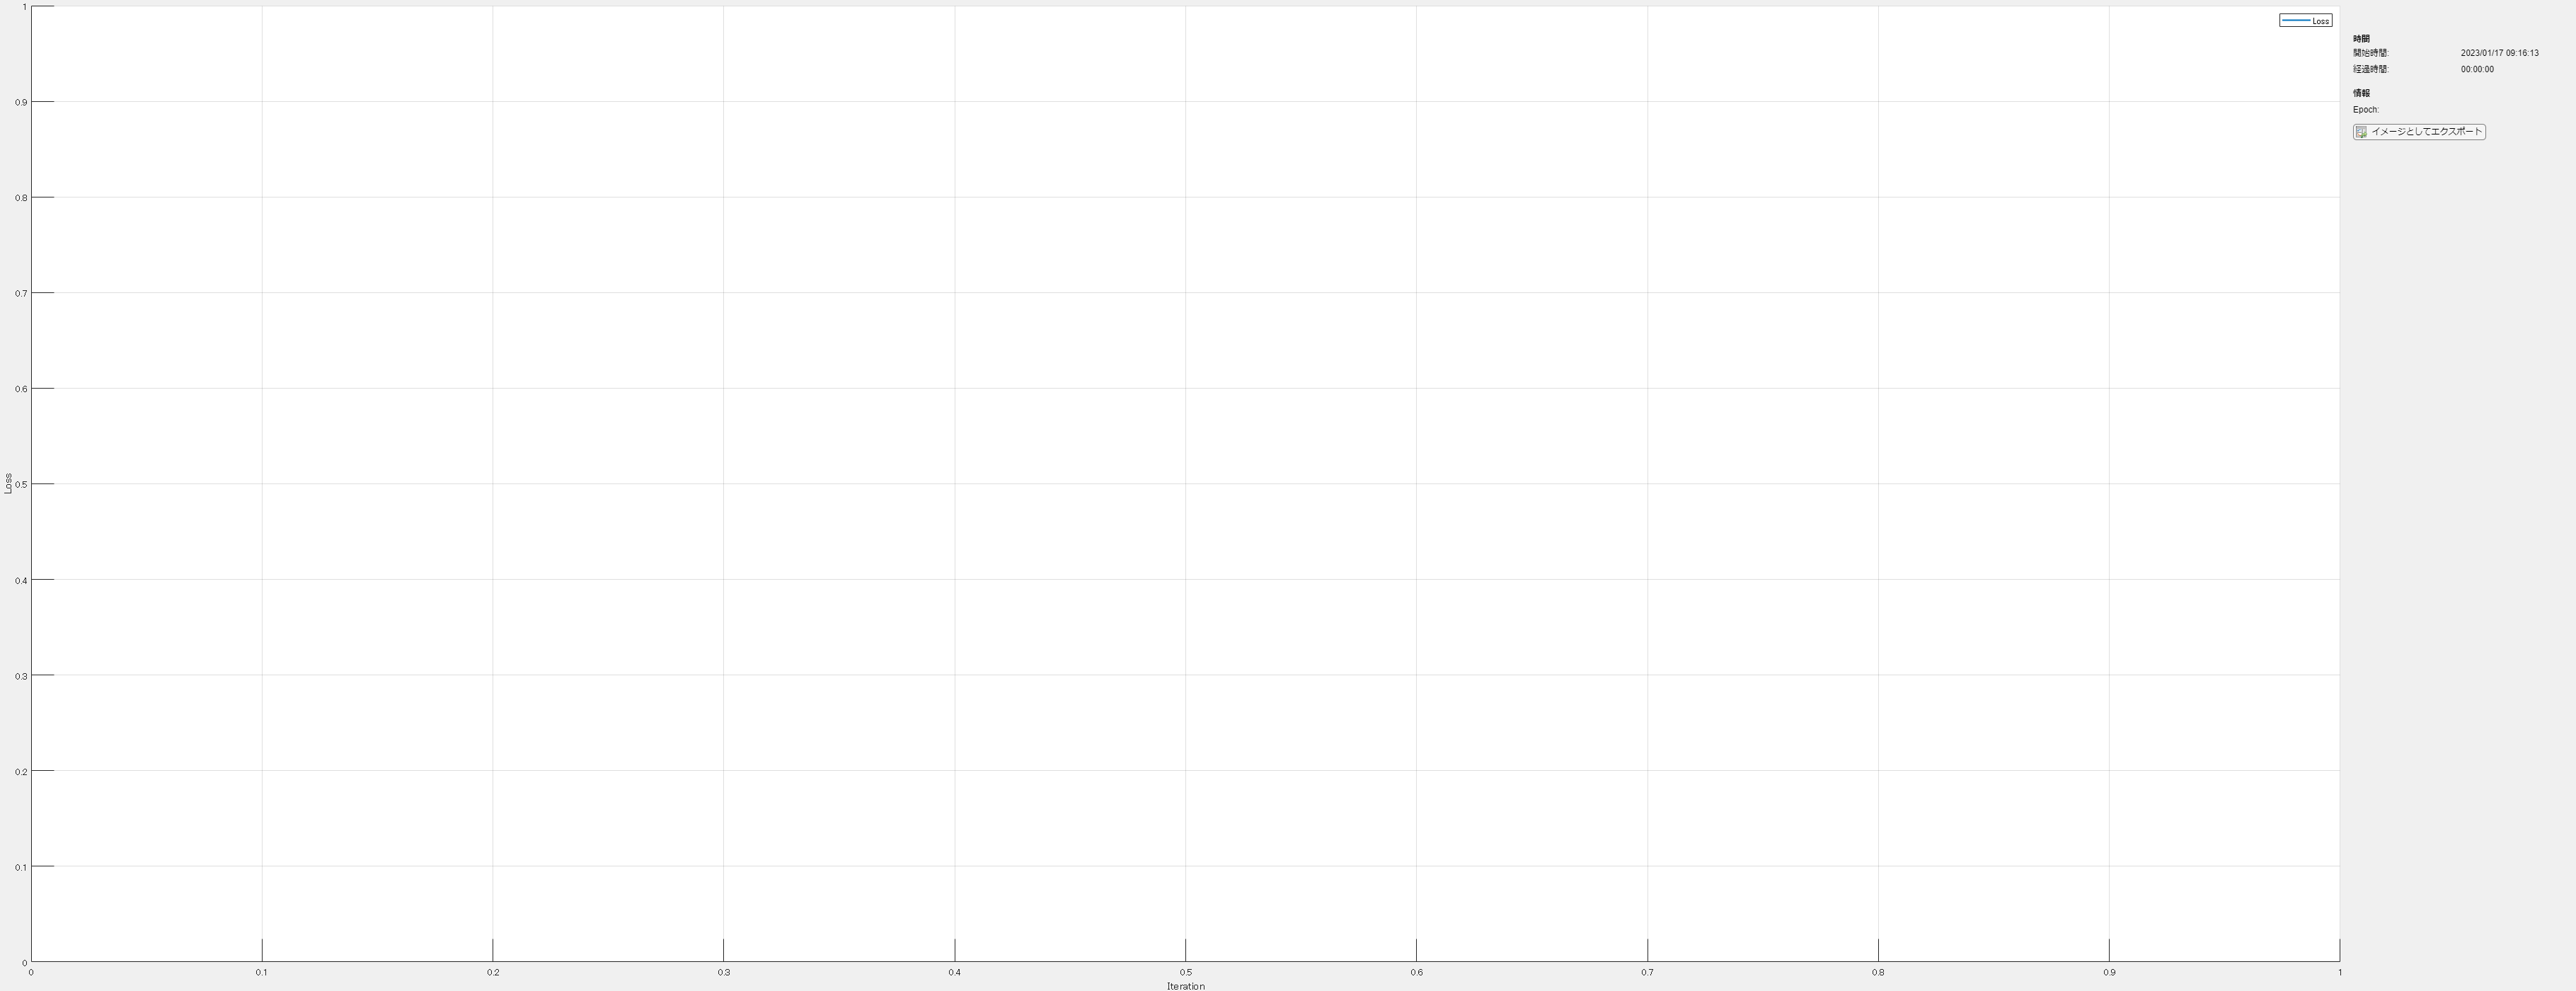

dlX = dlarray(gpuArray(arr(1,:)),"SSCB");
trainnet = dlnetwork(analysislgraph,dlX);
assert(trainnet.Initialized)
figure
monitor = trainingProgressMonitor(Metrics="Loss",Info="Epoch",XLabel="Iteration");

% lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
% ylim([0 inf])
% xlabel("Iteration")
% ylabel("Loss")
% grid on

### 最適化設計

学習用のパラメータ

- [深層学習用のミニバッチの作成 - MATLAB - MathWorks 日本](https://jp.mathworks.com/help/deeplearning/ref/minibatchqueue.html)

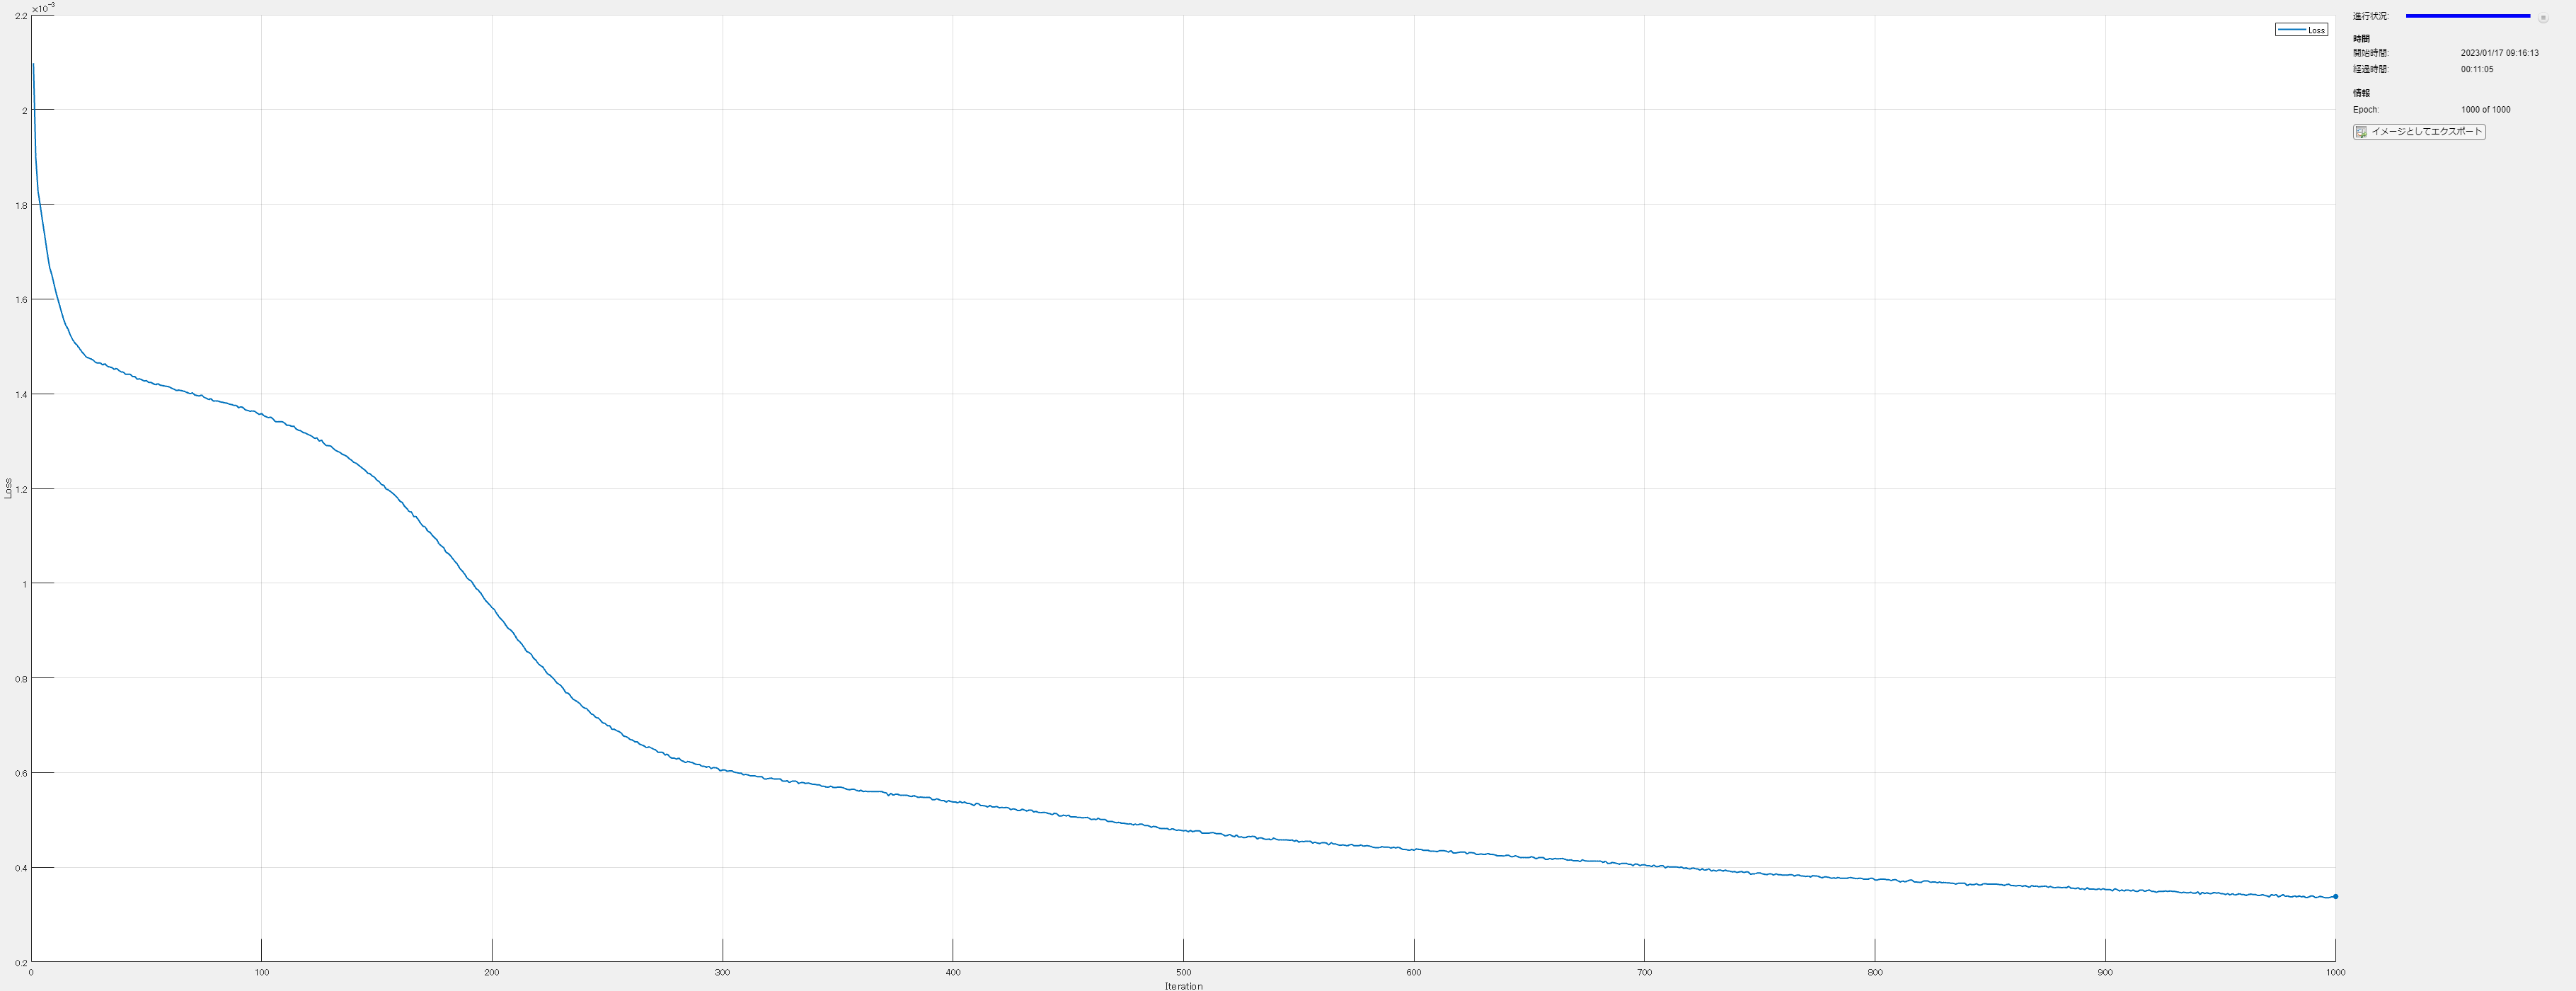

numEpochs = 1000; 
miniBatchSize = nT;
numObservationsTrain = nT;
numIterationsPerEpoch = ceil(numObservationsTrain / miniBatchSize);
numIterations = numEpochs * numIterationsPerEpoch;

% Minibatch
mbq = minibatchqueue(arrds,...
    "MinibatchSize",miniBatchSize,...
    "MiniBatchFcn",@(x) permute(cell2mat(x),[3 2 4 1]),...
    "OutputAsDlarray",1,...
    ..."OutputCast","double",...
    "MiniBatchFormat", "SSCB",...
    "OutputEnvironment", "gpu",...
    "PartialMiniBatch","discard");

% Training
averageGrad = [];
averageSqGrad = [];
iteration = 0;
epoch = 0;
start = tic;

% Loop over epochs.
while epoch < numEpochs && ~monitor.Stop
    epoch = epoch + 1;

    % Shuffle data.
    shuffle(mbq);

    % Loop over mini-batches.
    while hasdata(mbq) && ~monitor.Stop
        iteration = iteration + 1;

        % Read mini-batch of data.
        dlX = next(mbq);

        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelGradients function and update the network state.
        [loss,grad] = dlfeval(@modelLoss,trainnet,dlX);

        %Update the network parameters using the Adam optimizer.
        [trainnet,averageGrad,averageSqGrad] = ...
            adamupdate(trainnet,grad,averageGrad,averageSqGrad,iteration);

        % Display the training progress.
        recordMetrics(monitor,iteration,Loss=loss);
        updateInfo(monitor,Epoch=epoch + " of " + numEpochs);
        monitor.Progress = 100 * iteration/numIterations;
    end

end

## LSUN線形自己符号化器による近似 

import tansacnet.lsun.*
lsunlgraph = fcn_createcslsunlgraph1d([],...
    'InputSize',nX,...
    'Stride',stride,...
    'OverlappingFactor',kx,...
    ...'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Whole');
trainlgraph = layerGraph(trainnet);
lsunlgraph = fcn_cpparamsana2syn(lsunlgraph,trainlgraph);

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vx1 to Lv1_Cmp1_Vx1~
Copy angles from Lv1_Cmp1_Vx2 to Lv1_Cmp1_Vx2~


lsunlgraph = fcn_cpparamsana2syn_csax_(lsunlgraph,trainlgraph); 

Copy angles from Lv1_Cmp1_Qx1rb to Lv1_Cmp1_Qx1rb~
Copy angles from Lv1_Cmp1_Qx2lt to Lv1_Cmp1_Qx2lt~


lsunlgraph = fcn_cpparamssyn2ana(lsunlgraph,lsunlgraph);

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vx1~ to Lv1_Cmp1_Vx1
Copy angles from Lv1_Cmp1_Vx2~ to Lv1_Cmp1_Vx2


lsunlgraph = fcn_cpparamssyn2ana_csax_(lsunlgraph,lsunlgraph); 

Copy angles from Lv1_Cmp1_Qx1rb~ to Lv1_Cmp1_Qx1rb
Copy angles from Lv1_Cmp1_Qx2lt~ to Lv1_Cmp1_Qx2lt


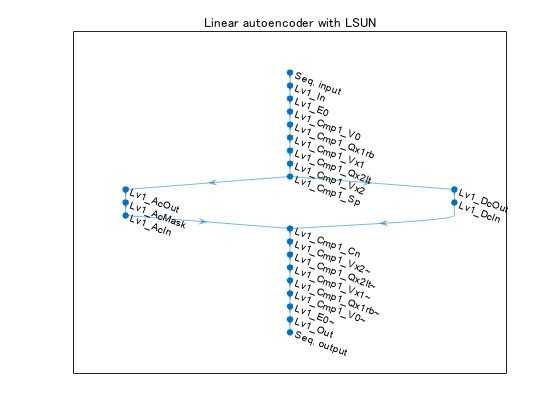


%nLevels = 1;
%for iLv = nLevels:-1:1S

% !!! 完全再構成を確認するためマスク処理を無効化
% coefMask = ones(nChsTotal,1);
iLv = 1;
strLv = sprintf('Lv%0d_',iLv);
lsunlgraph = lsunlgraph.disconnectLayers([strLv 'AcOut'],[strLv 'AcIn']);
% For AC
lsunlgraph = lsunlgraph.addLayers(...
    mask1dLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
lsunlgraph = lsunlgraph.connectLayers([strLv 'AcOut'],[strLv 'AcMask']);
lsunlgraph = lsunlgraph.connectLayers([strLv 'AcMask'],[strLv 'AcIn']);
%strLvPre = strLv;
%end
%

figure
plot(lsunlgraph)
title('Linear autoencoder with LSUN')

近似

lsunnet = assembleNetwork(lsunlgraph);
lsunseq = zeros(size(DataT),'like',DataT);
for iT = 1:nT
    lsunseq(iT,:) = lsunnet.predict(gpuArray(DataT(iT,:)));
end

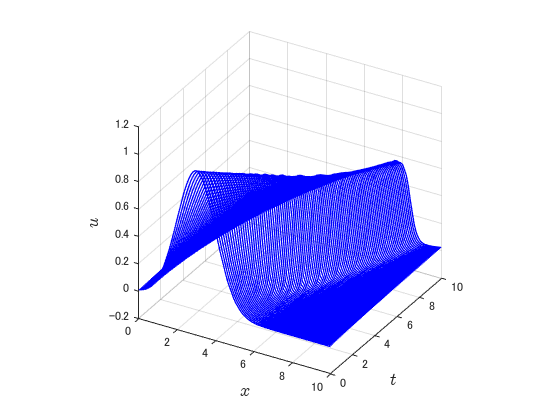

figure
disp_plot3_(T,X,lsunseq)

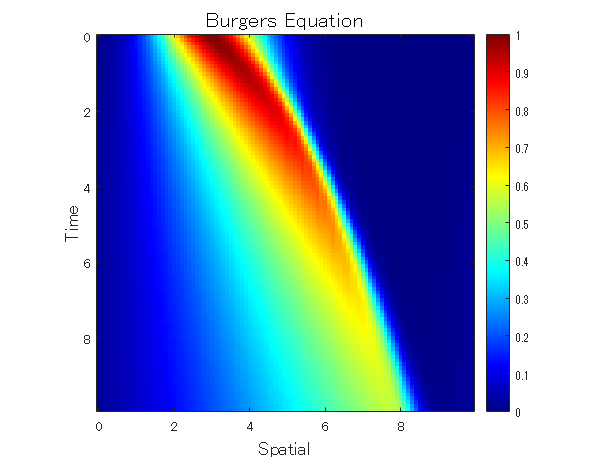

figure
disp_imagesc_(T,X,lsunseq)

% MSE評価
mse(DataT,lsunseq)

ans = 3.3552e-06

## Results 

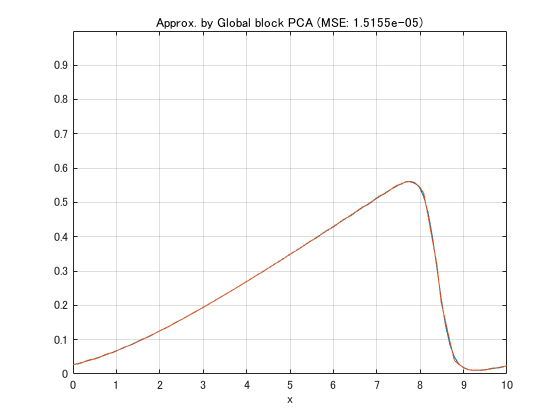

figure
ax = gca;
disp_plotmv_(ax,T,X,DataT,gbpcaseq)
title("Approx. by Global block PCA (MSE: " + num2str(mse(DataT,gbpcaseq))+")")

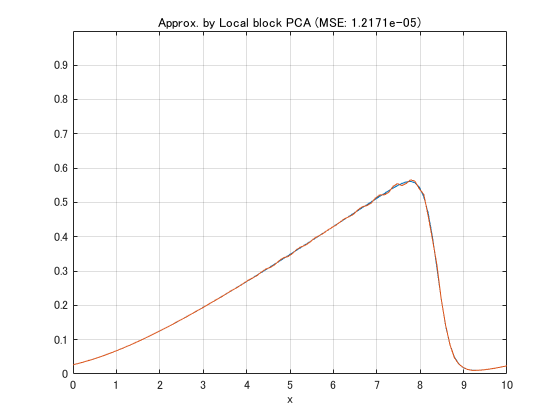

figure
ax = gca;
disp_plotmv_(ax,T,X,DataT,lbpcaseq)
title("Approx. by Local block PCA (MSE: " + num2str(mse(DataT,lbpcaseq))+")")

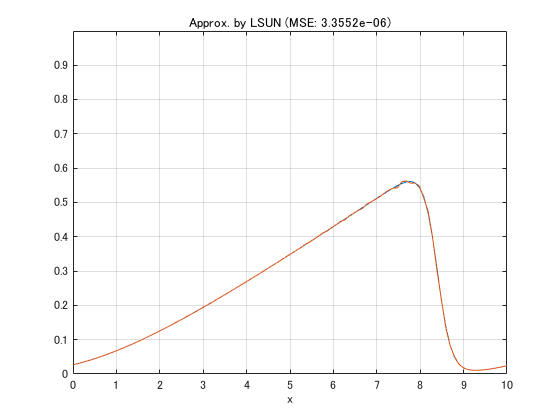


figure
ax = gca;
disp_plotmv_(ax,T,X,DataT,lsunseq)
title("Approx. by LSUN (MSE: " + num2str(mse(DataT,lsunseq))+")")

### 関数定義

Peter Mao (2023). fftfreq (https://www.mathworks.com/matlabcentral/fileexchange/67026-fftfreq), MATLAB Central File Exchange. 取得済み January 6、2023.

function f=fftfreq(npts,dt,alias_dt)
% returns a vector of the frequencies corresponding to the length
% of the signal and the time step.
% specifying alias_dt > dt returns the frequencies that would
% result from subsampling the raw signal at alias_dt rather than
% dt.
    
    
  if (nargin < 3)
      alias_dt = dt;
  end
  fmin = -1/(2*dt);
  df = 1/(npts*dt);
  f0 = -fmin;
  alias_fmin = -1/(2*alias_dt);
  f0a = -alias_fmin;
  
  ff = mod(linspace(0, 2*f0-df, npts)+f0,  2*f0)  - f0;
  fa = mod(                        ff+f0a, 2*f0a) - f0a;
  %  return the aliased frequencies
  f = fa;
end

Definition of ODE system (PDE ---(FFT)---> ODE system)

%Definition of ODE system (PDE ---(FFT)---> ODE system)
function u_t_real = burg_system(u, t, k,mu,nu)
    %Spatial derivative in the Fourier domain
    u_hat = fft(u);
    u_hat_x = 1j*k(:).*u_hat;
    u_hat_xx = -(k(:).^2).*u_hat;
    
    %Switching in the spatial domain
    u_x = ifft(u_hat_x);
    u_xx = ifft(u_hat_xx);
    
    %ODE resolution
    u_t = -mu*u.*u_x + nu*u_xx;
    u_t_real = real(u_t);
end

Function to extract a local patch block from a global array

function y = fcn_extract_blks_(x,iBlk,blksz,kx)
% Extend array x
padsz = [0 (kx-1)*blksz/2];
xx = padarray(x,padsz,"circular");
%
posx = (iBlk-1)*blksz+1;
y = xx(:,posx:posx+kx*blksz-1);
end

Function to place a local patch block to a global array

function y = fcn_place_blks_(y,blk,iBlk,blksz)
% Extend array x
posx = (iBlk-1)*blksz+1;
y(:,posx:posx+blksz-1) = blk;
end

Loss function

    $L(\mathbf{\theta}) = \|\mathbf{x}\|_2^2-\|F_\mathbf{\theta}(\mathbf{x})\|_2^2$,

where $F_\mathbf{\theta}(\cdot)$ is a unitaly analyzer with a coefficient mask. $L(\mathbf{\theta})\geq 0$ is guaranteed.

function [loss,gradients] = modelLoss(dlnet, dlX)
% Forward data through the dlnetwork object.
dlY = forward(dlnet,dlX); % F(x)
% Compute loss.
Nx = size(dlX,4);
Ny = size(dlY,4);
loss = sum(dlX.^2,"all")/Nx-sum(dlY.^2,"all")/Ny;
% Compute gradients.
gradients = dlgradient(loss,dlnet.Learnables);
loss = double(gather(extractdata(loss)));
end

function disp_plot3_(T,X,DataT,c)
if nargin < 4
    c = 'blue';
end
for idx = 1:length(X)
    plot3(X,T(idx)*ones(size(X)),DataT(idx,:),...
        'Color',c,...
        'LineWidth',1)
    hold on
end
xlabel('$x$', 'FontSize',14,'Interpreter','latex')
ylabel('$t$', 'FontSize',14,'Interpreter','latex')
zlabel('$u$', 'FontSize',14,'Interpreter','latex')
ax = gca;
ax.View = [30 30];
ax.PlotBoxAspectRatio = [ 1 1 1];
grid on
hold off
end

function disp_imagesc_(T,X,DataT)
imagesc(DataT)
colormap("jet")
colorbar
title('Burgers Equation','FontSize',15)
xlabel('Spatial','FontSize',12)
ylabel('Time','FontSize',12)
ax = gca;
ax.PlotBoxAspectRatio = [1 1 1];
ax.XTick = 1:20:100;
ax.XTickLabel = round(X(ax.XTick));
ax.YTick = 1:20:100;
ax.YTickLabel = round(T(ax.YTick));
end

function disp_plotmv_(ax,T,X,DataT,AprxT)
    a = DataT(1,:);
    b = AprxT(1,:);
    p = plot(ax,X,a,X,b);
    axis([min(X) max(X) min(DataT(:)) max(DataT(:))])
    xlabel('x')
    grid on
    hold on
    drawnow
    for iT = 2:length(T)
        a = DataT(iT,:);
        b = AprxT(iT,:);
        p(1).YData = a;
        p(2).YData = b;
        drawnow
    end
    hold off
end

function synthesislgraph = fcn_cpparamsana2syn_csax_(synthesislgraph,analysislgraph)
expanalyzer = '^Lv\d+_Cmp\d+_Q(\w\d|0)+(\w)+$';
nLayers = height(analysislgraph.Layers);
for iLayer = 1:nLayers
    alayer = analysislgraph.Layers(iLayer);
    alayerName = alayer.Name;
    if ~isempty(regexp(alayerName,expanalyzer,'once'))
        slayer = synthesislgraph.Layers({synthesislgraph.Layers.Name} == alayerName + "~");
        slayer.Angles = alayer.Angles;
        synthesislgraph = synthesislgraph.replaceLayer(slayer.Name,slayer);
        disp("Copy angles from " + alayerName + " to " + slayer.Name)
    end
end
end

function analysislgraph = fcn_cpparamssyn2ana_csax_(synthesislgraph,analysislgraph)
expanalyzer = '^Lv\d+_Cmp\d+_Q(\w\d|0)+(\w)+$';
nLayers = height(analysislgraph.Layers);
for iLayer = 1:nLayers
    alayer = analysislgraph.Layers(iLayer);
    alayerName = alayer.Name;
    if ~isempty(regexp(alayerName,expanalyzer,'once'))
        slayer = synthesislgraph.Layers({synthesislgraph.Layers.Name} == alayerName + "~");
        alayer.Angles = slayer.Angles;
        analysislgraph = analysislgraph.replaceLayer(alayerName,alayer);
        disp("Copy angles from " + slayer.Name + " to " + alayerName)
    end
end
end